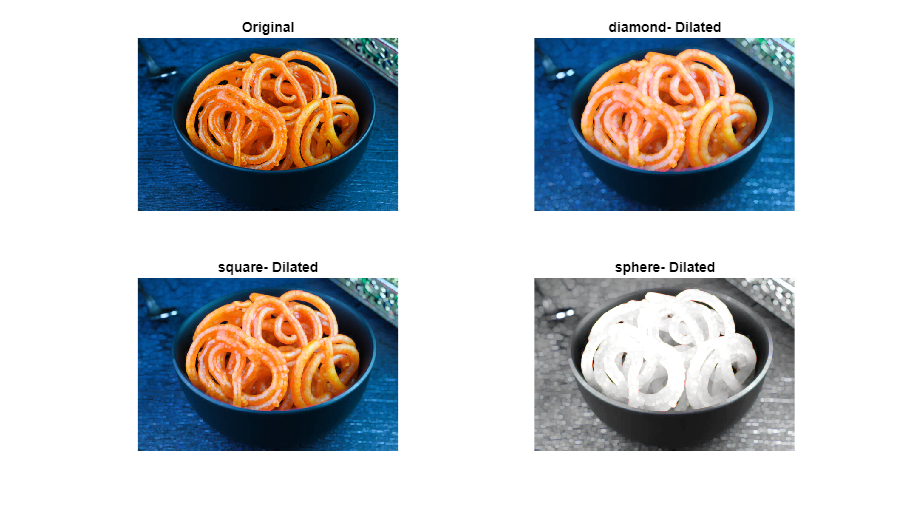

 
[fname, fpath] = uigetfile( ...
    {'*.png;*.jpg;*jpeg}'}, ...
    'Select Image' ...
);
img = imread([fpath, fname]);

r = 4;
shapes = ["diamond", "square", "sphere"];

figure(Position=[0 0 1920 1080]);
subplot(2,2,1);
imshow(img);
title("Original");
for i = 1 : length(shapes)
    subplot(2, 2, i+1);
    se = strel(shapes(i), r);
    dilated = imdilate(img, se);
    imshow(dilated);
    title(strcat(shapes(i), '- Dilated'));
end

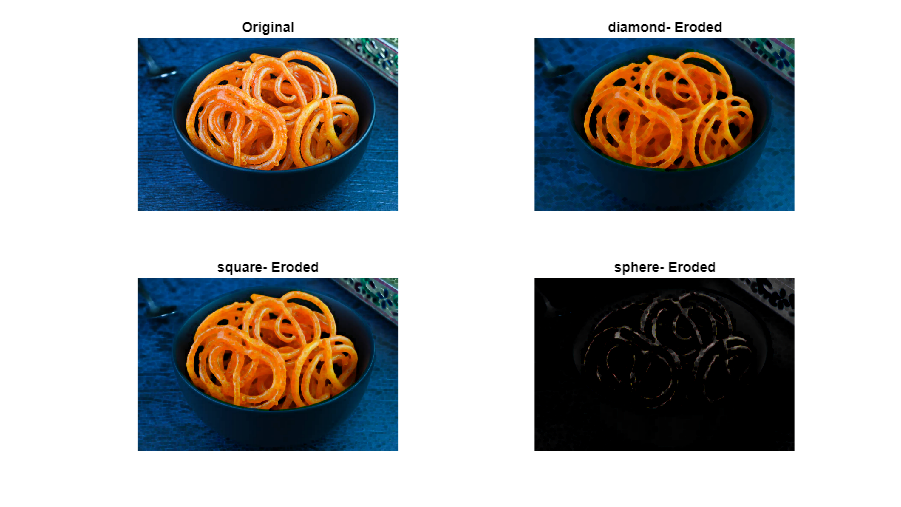

figure(Position=[0 0 1920 1080]);
subplot(2,2,1);
imshow(img);
title("Original");
for i = 1 : length(shapes)
    subplot(2, 2, i+1);
    se = strel(shapes(i), r);
    eroded = imerode(img, se);
    imshow(eroded);
    title(strcat(shapes(i), '- Eroded'));
end

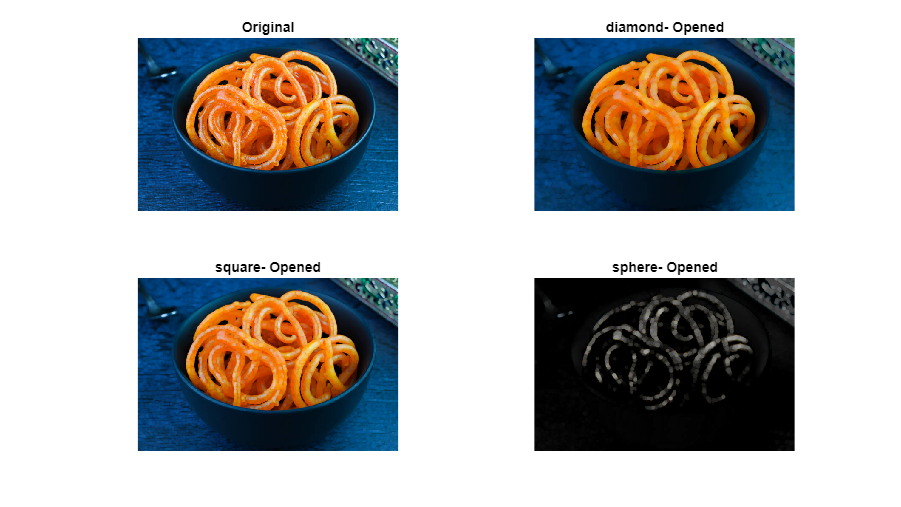

% open = erosion followed by dilation
figure(Position=[0 0 1920 1080]);
subplot(2,2,1);
imshow(img);
title("Original");
for i = 1 : length(shapes)
    subplot(2, 2, i+1);
    se = strel(shapes(i), r);
    opened = imopen(img, se);
    imshow(opened);
    title(strcat(shapes(i), '- Opened'));
end

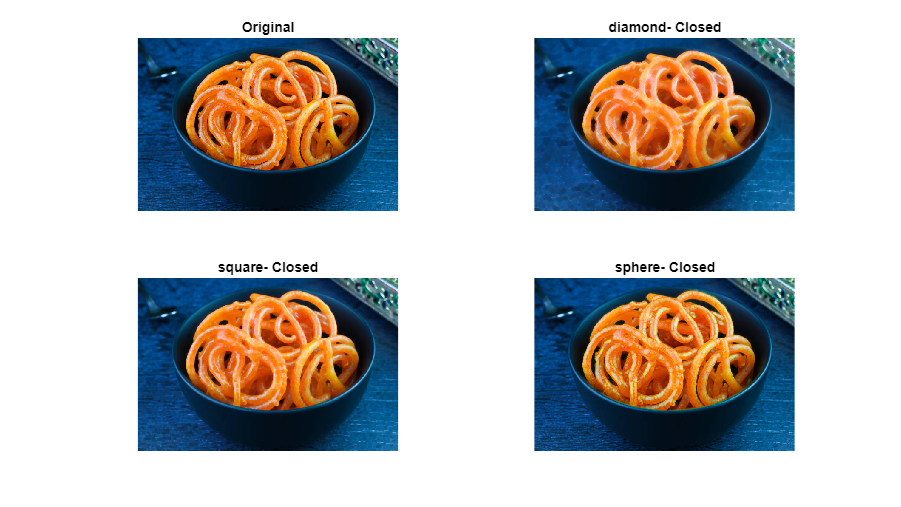

% close = dilation followed by erosion followed
figure(Position=[0 0 1920 1080]);
subplot(2,2,1);
imshow(img);
title("Original");
for i = 1 : length(shapes)
    subplot(2, 2, i+1);
    se = strel(shapes(i), r);
    closed = imclose(img, se);
    imshow(closed);
    title(strcat(shapes(i), '- Closed'));
end